clearvars;
%inputs
format shortG
xmin = -7;
xmax = 7;
ymin = -7;
ymax = 7;
zmin = 0;
zmax = 1.5;
xint = 0.2;
yint = 0.2;
zint = 0.2;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
datasize = xtotal*ytotal*ztotal;
lsberr = 67626;

mu_0 = 4*pi*10^-7; % T m/A^2
diameter = 4.98; %m
length = 1.97; %m
Br = 14800/10000; %T
V = (diameter/2)^2*pi*length; %m^3
dipole_moment = Br * V / mu_0; %A m^2
M_0 = dipole_moment/V; %A/m
B_t = mu_0*V*M_0/(4*pi); %T m^3

sensor = [0, 0, -33];
lsb = 0.008/1000; %mT
%H_0 = repelem([0 0 1], [datasize], [1]);

import = importdata('C:\Users\nguye\Documents\GitHub\magnetic-sensor-data\PIM_03202023\DataAvg.txt'); %mT
dataavg = import.data

dataavg =             0          6.6         -4.2          0.4     -0.71712      0.12252      -1.4209    0.0010904    0.0015664    0.0014956
            1         -2.6          1.8          1.4      -0.1412     -0.31516      -1.5796    0.0020187     0.001621    0.0014644
            2            2         -3.8          1.4     -0.40845     0.097074      -1.6226    0.0012069    0.0023225     0.001545
            3         -2.4         -2.6          0.8     -0.18262    0.0014378      -1.8043    0.0013363    0.0014688    0.0014963
            4           -1          3.2            0     -0.26802     -0.47018      -1.6289    0.0013126    0.0024676    0.0013326
            5          1.8          6.6          0.6     -0.33462     -0.56993       -1.283    0.0013744    0.0015077    0.0013478
            6           -4          2.6            0     -0.04656     -0.44372      -1.7194    0.0014556    0.0016862    0.0014559
            7          3.2         -5.6            0     -0.58984      0.

% davg.data;
dataavg = dataavg(:, 2:7)

dataavg =           6.6         -4.2          0.4     -0.71712      0.12252      -1.4209
         -2.6          1.8          1.4      -0.1412     -0.31516      -1.5796
            2         -3.8          1.4     -0.40845     0.097074      -1.6226
         -2.4         -2.6          0.8     -0.18262    0.0014378      -1.8043
           -1          3.2            0     -0.26802     -0.47018      -1.6289
          1.8          6.6          0.6     -0.33462     -0.56993       -1.283
           -4          2.6            0     -0.04656     -0.44372      -1.7194
          3.2         -5.6            0     -0.58984      0.25345        -1.69
         -3.4         -5.8          1.2     -0.10348      0.26517      -1.7725
            5          2.2            0     -0.63191     -0.33065      -1.4062


dataavg= sortrows(dataavg, [3 2 1]);
%datamode = importdata('C:\Users\nguye\OneDrive\Watanabe_Project\PIM03162023mode.txt'); %mT
dataavg = [dataavg(:,1:3) -dataavg(:,5) -dataavg(:,4) dataavg(:,6)]; %rearrange b field components to match printer axes

lsberror = {};
z = zmin;
locpred = [];
Bpred = [];
% datamode = [];
% dataavg = [];
location = [];

for k = 1:ztotal
    zstr = sprintf('%.1f', z);
    y = ymin;

    for j = 1:ytotal
        ystr = sprintf('%.1f', y);
        x = xmin;

        for i = 1:xtotal
%             location = [location; x y z];
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM03162023\',xstr,'_',ystr,'_',zstr,'.data');
%             test = parquetread(filename);
%             
%             b_x = test.Magnetometerx;
%             xavg = mean(b_x);
%             xmode1 = mode(b_x);
%             b_x(b_x==xmode1) = NaN;
%             xmode2 = mode(b_x);
%             xerr = abs(xmode2-xmode1);
% 
%             b_y = test.Magnetometery;
%             yavg = mean(b_y);
%             ymode1 = mode(b_y);
%             b_y(b_y==ymode1) = NaN;
%             ymode2 = mode(b_y);
%             yerr = abs(ymode2-ymode1);
% 
%             b_z = test.Magnetometerz;
%             zavg = mean(b_z);
%             zmode1 = mode(b_z);
%             b_z(b_z==zmode1) = NaN;
%             zmode2 = mode(b_z);
%             zerr = abs(zmode2-zmode1);
%             datamode = [datamode; [xmode1 ymode1 zmode1]];
%             dataavg = [dataavg; [xavg yavg zavg]];

%             
% 
%             syms a b c;
%             eqns = [3*(-1-c)*(-a)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == xmode1, ...
%                 3*(-1-c)*(-b)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == ymode1, ...
%                 3*(-1-c)*(-1-c)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 - 1/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^3 == zmode1];
%             S = solve(eqns, 'Real', true);
%             xmat = vpa(S.a);
%             ymat = vpa(S.b);         
%             zmat = vpa(S.c);
%             locmat = [xmat ymat zmat]
%             mask = any(imag(locmat),2);
%             locmat(mask,:)=[];
%             locmat = [xmat ymat zmat];
%             if size(locmat, 1) > 1
%                 locpred = [locpred; mean(locmat)];
%             else
%                 locpred = [locpred; locmat];
%             end
%             
%             magnet = [x y z];
%             R = norm(magnet - sensor);
%             Bx = B_t*3*(magnet(3)-sensor(3))*(magnet(1)-sensor(1))/R^5;
%             By = B_t*3*(magnet(3)-sensor(3))*(magnet(2)-sensor(2))/R^5;
%             Bz = B_t*3*(magnet(3)-sensor(3))*(magnet(3)-sensor(3))/R^5 + 1/R^3;
%             Bpred = [Bpred; [Bx, By, Bz]];
% 
%             x = x + xint;
%             if isnan(xerr) && isnan(yerr) && isnan(zerr)
%                 x = x + xint;
%             elseif xerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             elseif yerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             elseif zerr > lsb
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror; loc];
%                 x = x + xint;
%             else
%                 x = x + xint;
%             end
        end
        y = y + yint;
    end
    z = z + zint
end

z =           0.2


z =           0.4


z =           0.6


z =           0.8


z =      1


z =           1.2


z =           1.4


z =           1.6



% datamode = [location datamode];
% dataavg = [location dataavg];

% writematrix(datamode, 'C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM03162023\mode.txt')
% writematrix(dataavg, 'C:\Users\Brandon Nguyen\Documents\GitHub\magnetic-sensor-data\PIM03162023\avg.txt')

%B = B_t*(3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)*10^12;
% B_t = Br*V/(4*pi);
sensor = [-5 2.5 -33]
X = sensor - dataavg(:,1:3);
R = sqrt(sum(X.^2, 2));
B_not = (3*dot(M_0, X, 2).*X./R.^5-M_0./R.^3)*10^12;

Error using dot
A and B must be same size.

xfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,1))./R.^5)*10^12;
beta0 = [0];
mdlx = fitnlm(dataavg(:,1:3), dataavg(:,4), xfieldfun, beta0)
yfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,2))./R.^5)*10^12;
mdly = fitnlm(dataavg(:,1:3), dataavg(:,5), yfieldfun, beta0)
zfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-1-x(:,3))./R.^5-1./R.^3)*10^12;
mdlz = fitnlm(dataavg(:,1:3), dataavg(:,6), zfieldfun, beta0)

% syms b;
% bx = (b*V/(4*pi))*(3*(-1-X(:,3)).*(-X(:,1))./R.^5)*10^12 - dataavg(:,4);
% by = (b*V/(4*pi))*(3*(-1-X(:,3)).*(-X(:,2))./R.^5)*10^12 - dataavg(:,5);
% bz = (b*V/(4*pi))*(3*(-1-X(:,3)).*(-1-X(:,3))./R.^5-1./R.^3)*10^12 - dataavg(:,6);
% 
% sol = solve([bx, by, bz], b)

bx = table2array(mdlx.Coefficients);
by = table2array(mdly.Coefficients);
bz = table2array(mdlz.Coefficients);
B_tguess = (bx(1)+by(1)+bz(1))/3
B_guess = B_tguess.*V/(4*pi)*B_not
dataavg(:,4:6)
B_guess = [dataavg(:, 1:3) B_guess];

% bfieldfun = @(b, x, y)(b*V/(4*pi))*(3*dot(y, (sensor-x), 2).*(sensor-x)./(sqrt(sum((sensor-x).^2,2))).^5-y./(sqrt(sum((sensor-x).^2,2))).^3)*10^12;
B_t;
% X = sensor - location = (0, 0, -33) - location
bfun = @(x)[3*(-1-(-33-x(:,3))).*(-5-x(:,1)*10^12)./((-5-x(:,1)).^2+(-2.5-x(:,2)).^2+(-33-x(:,3)).^2).^(5/2) - dataavg(:,4), 3*(-1-(-33-x(:,3))).*(-2.5-x(:,2)*10^12)./((-5-x(:,1)).^2+(-2.5-x(:,2)).^2+(-33-x(:,3)).^2).^(5/2) - dataavg(:,5), 3*(-1-(-33-x(:,3))).*(-33-x(:,3)*10^12)./((-5-x(:,1)).^2+(-2.5-x(:,2)).^2+(-33-x(:,3)).^2).^(5/2) ...
     - 1/((-x(:,1)).^2+(-x(:,2)).^2+(-33-x(:,3)).^2).^(3/2) - dataavg(:,6)];
x0 = [0, 0, 0];
locpred = lsqnonlin(bfun, x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


locpred =      -7.24556682661738e-08     -1.32084843635944e-07      6.90443507211151e-07


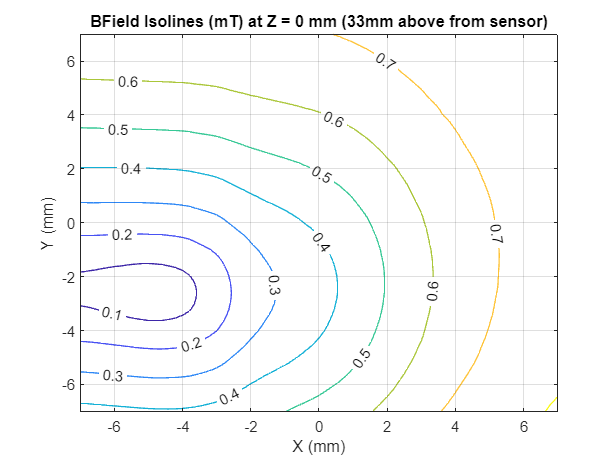

format longG
zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [71 71]);
zerox = reshape(zzeromat(:,1), [71 71]);
zeroy = reshape(zzeromat(:,2), [71 71]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

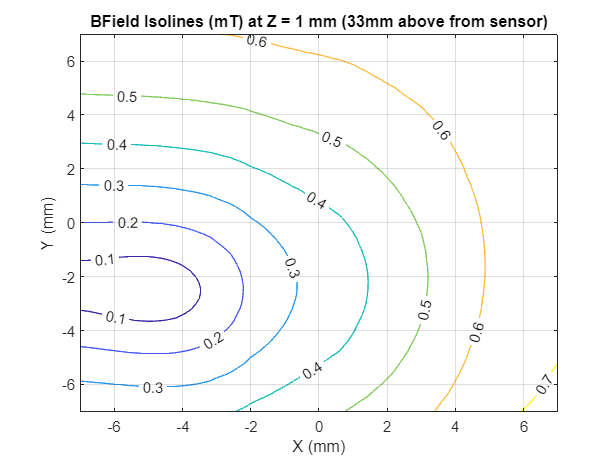


ztwo = find(abs(dataavg(:,3)-1) < 0.1);

ztwomat = dataavg(ztwo,:);
twoB = sqrt(sum(ztwomat(:,4:5).^2,2));
twoB = reshape(twoB, [71 71]);
twox = reshape(ztwomat(:,1), [71 71]);
twoy = reshape(ztwomat(:,2), [71 71]);

contour(twox, twoy, twoB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 1 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;


zfour = find(abs(dataavg(:,3)-4) < 0.1);

zfourmat = dataavg(zfour,:);
fourB = sqrt(sum(zfourmat(:,4:5).^2,2));
fourB = reshape(fourB, [51 51]);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

fourx = reshape(zfourmat(:,1), [51 51]);
foury = reshape(zfourmat(:,2), [51 51]);

contour(fourx, foury, fourB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

x0 = find(abs(dataavg(:,1)) <= 0.1);
x1 = find(abs(dataavg(:,1)-1) <= 0.1);
x2 = find(abs(dataavg(:,1)-2) <= 0.1);
x3 = find(abs(dataavg(:,1)-3) <= 0.1);
x4 = find(abs(dataavg(:,1)-4) <= 0.1);
x5 = find(abs(dataavg(:,1)-5) <= 0.1);
xm1 = find(abs(dataavg(:,1)+1) <= 0.1);
xm2 = find(abs(dataavg(:,1)+2) <= 0.1);
xm3 = find(abs(dataavg(:,1)+3) <= 0.1);
xm4 = find(abs(dataavg(:,1)+4) <= 0.1);
xm5 = find(abs(dataavg(:,1)+5) <= 0.1);

y0 = find(abs(dataavg(:,2)) <= 0.1);
y1 = find(abs(dataavg(:,2)-1) <= 0.1);
y2 = find(abs(dataavg(:,2)-2) <= 0.1);
y3 = find(abs(dataavg(:,2)-3) <= 0.1);
y4 = find(abs(dataavg(:,2)-4) <= 0.1);
y5 = find(abs(dataavg(:,2)-5) <= 0.1);
ym1 = find(abs(dataavg(:,2)+1) <= 0.1);
ym2 = find(abs(dataavg(:,2)+2) <= 0.1);
ym3 = find(abs(dataavg(:,2)+3) <= 0.1);
ym4 = find(abs(dataavg(:,2)+4) <= 0.1);
ym5 = find(abs(dataavg(:,2)+5) <= 0.1);


z0 = find(abs(dataavg(:,3)) <= 0.1);
z1 = find(abs(dataavg(:,3)-1) <= 0.1);
z2 = find(abs(dataavg(:,3)-2) <= 0.1);
z3 = find(abs(dataavg(:,3)-3) <= 0.1);
z4 = find(abs(dataavg(:,3)-4) <= 0.1);
z5 = find(abs(dataavg(:,3)-5) <= 0.1);

xx = [x1; x2; x3; x4; x5; xm1; xm2; xm3; xm4; xm5];
yy = [y1; y2; y3; y4; y5; ym1; ym2; ym3; ym4; ym5];
zz = [z0; z1; z2; z3; z4; z5];

zy = zz(ismember(zz,yy));
index = zy(ismember(zy, xx));
dataavg(index, :);

quiver3(dataavg(:,1), dataavg(:,2), dataavg(:,3), dataavg(:,4)*2, dataavg(:,5)*2, dataavg(:,6)*2, 'b')
hold on;
axis([-7 7 --7 7 0 1])
title('BField Vectors')
xlabel('X (mm)')
ylabel('Y (mm)')
zlabel('Z (mm)')
hold off;

dataavg

N35 lookup "default" value for magnetic field strength.

Fit for orientation (H vector_, calibrate according to simulated B field.

Optimize distance between sensors in a square